# Call Python from MATLAB

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

Check that MATLAB can recognize the Python installation. 

cd(fileparts(matlab.desktop.editor.getActiveFilename));
pyenv

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\Users\dsportil\AppData\Local\Programs\Python\Python39\pythonw.exe"
          Library: "C:\Users\dsportil\AppData\Local\Programs\Python\Python39\python39.dll"
             Home: "C:\Users\dsportil\AppData\Local\Programs\Python\Python39"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "25404"
      ProcessName: "MATLAB"


Just add `py.` to call functions.

py.math.sqrt(42)

ans = 6.4807

You can also use a Live Task

% Python code input
pycode = [...
"import math",...
"",...
"a = math.sqrt(42)"...
];

try
    [a] = pyrun(pycode, ...
         [ "a" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

a = 6.4807


% Clear temporary variables from workspace and from Python
clear pycode;

Use MATLAB name=value syntax for Python named arguments. Python is often more strict than MATLAB about data types. 

hw = py.textwrap.wrap("Hello world!", width = int8(2))

hw =   Python list with values:

    ['He', 'll', 'o ', 'wo', 'rl', 'd!']

    Use string, double or cell function to convert to a MATLAB array.


Convert to appropriate MATLAB type, if desired.

hw = string(hw)

hw = 1×6 string array
    "He"    "ll"    "o "    "wo"    "rl"    "d!"


## Read weather data using Python module 

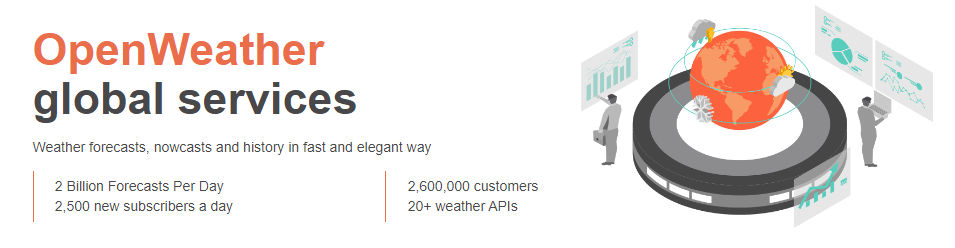

The weather.py module reads and parses current weather data from the web API: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

% apikey = readtable("accessKey.txt","TextType","string"); 

Or use the sample API key

appid ='b1b15e88fa797225412429c1c50c122a1';

Use the weather.py module to get the air quality for London. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("London","UK",appid,api='samples')

jsonData =   Python dict with no properties.

    {'coord': {'lon': -0.13, 'lat': 51.51}, 'weather': [{'id': 300, 'main': 'Drizzle', 'description': 'light intensity drizzle', 'icon': '09d'}], 'base': 'stations', 'main': {'temp': 280.32, 'pressure': 1012, 'humidity': 81, 'temp_min': 279.15, 'temp_max': 281.15}, 'visibility': 10000, 'wind': {'speed': 4.1, 'deg': 80}, 'clouds': {'all': 90}, 'dt': 1485789600, 'sys': {'type': 1, 'id': 5091, 'message': 0.0103, 'country': 'GB', 'sunrise': 1485762037, 'sunset': 1485794875}, 'id': 2643743, 'name': 'London', 'cod': 200}


Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 280.32, 'pressure': 1012, 'humidity': 81, 'temp_min': 279.15, 'temp_max': 281.15, 'speed': 4.1, 'deg': 80, 'lon': -0.13, 'lat': 51.51, 'city': 'London', 'current_time': '2025-05-15 12:09:26.268442'}


## Preprocess data 

The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

data = struct with fields:
            temp: 280.3200
        pressure: [1×1 py.int]
        humidity: [1×1 py.int]
        temp_min: 279.1500
        temp_max: 281.1500
           speed: 4.1000
             deg: [1×1 py.int]
             lon: -0.1300
             lat: 51.5100
            city: [1×6 py.str]
    current_time: [1×26 py.str]


Convert the remaining python types to the desired MATLAB data types.

string(data.city)

ans = "London"

Perform the remaining conversions using custom `convertData` function. 

convertData(data)

ans = 1×9 table
      T        P      RH    WindSpd    WindDir     lon      lat       city           DateLocal      
    ______    ____    __    _______    _______    _____    _____    ________    ____________________

    280.32    1012    81      4.1        80       -0.13    51.51    "London"    15-May-2025 12:09:26


## Handle timeseries with the weather forecast

Now let's look at the weather forecast for this week in Munich.

jsonData = py.weather.get_forecast('Lille','FR',appid,api='samples');
forecastData = py.weather.parse_forecast_json(jsonData);  
forecast = struct(forecastData)

forecast = struct with fields:
    current_time: [1×36 py.list]
            temp: [1×36 py.list]
             deg: [1×36 py.list]
           speed: [1×36 py.list]
        humidity: [1×36 py.list]
        pressure: [1×36 py.list]


The type of data returned by the parsed forecast date is a **Python array**:

forecast.temp

ans =   Python list with values:

    [286.67, 285.66, 277.05, 272.78, 273.341, 275.568, 276.478, 276.67, 278.253, 276.455, 275.639, 275.459, 275.035, 274.965, 274.562, 275.648, 277.927, 278.367, 273.797, 271.239, 269.553, 268.198, 267.295, 272.956, 277.422, 277.984, 272.459, 269.473, 268.793, 268.106, 267.655, 273.75, 279.302, 279.343, 274.443, 272.424]

    Use string, double or cell function to convert to a MATLAB array.


Convert to a MATLAB double array (en from Kelvin to Celsius)

temp = double(forecast.temp) - 273.15

temp =    13.5200   12.5100    3.9000   -0.3700    0.1910    2.4180    3.3280    3.5200    5.1030    3.3050    2.4890    2.3090    1.8850    1.8150    1.4120    2.4980    4.7770    5.2170    0.6470   -1.9110   -3.5970   -4.9520   -5.8550   -0.1940    4.2720    4.8340   -0.6910   -3.6770   -4.3570   -5.0440   -5.4950    0.6000    6.1520    6.1930    1.2930   -0.7260


Current time is a list of strings.

forecast.current_time

ans =   Python list with values:

    ['2017-02-16 12:00:00', '2017-02-16 15:00:00', '2017-02-16 18:00:00', '2017-02-16 21:00:00', '2017-02-17 00:00:00', '2017-02-17 03:00:00', '2017-02-17 06:00:00', '2017-02-17 09:00:00', '2017-02-17 12:00:00', '2017-02-17 15:00:00', '2017-02-17 18:00:00', '2017-02-17 21:00:00', '2017-02-18 00:00:00', '2017-02-18 03:00:00', '2017-02-18 06:00:00', '2017-02-18 09:00:00', '2017-02-18 12:00:00', '2017-02-18 15:00:00', '2017-02-18 18:00:00', '2017-02-18 21:00:00', '2017-02-19 00:00:00', '2017-02-19 03:00:00', '2017-02-19 06:00:00', '2017-02-19 09:00:00', '2017-02-19 12:00:00', '2017-02-19 15:00:00', '2017-02-19 18:00:00', '2017-02-19 21:00:00', '2017-02-20 00:00:00', '2017-02-20 03:00:00', '2017-02-20 06:00:00', '2017-02-20 09:00:00', '2017-02-20 12:00:00', '2017-02-20 15:00:00', '2017-02-20 18:00:00', '2017-02-20 21:00:00']

    Use string, double or cell function to convert to a MATLAB ar

Convert to a MATLAB string, and then to a MATLAB datetime:

time = datetime(string(forecast.current_time))

time = 1×36 datetime array
   16-Feb-2017 12:00:00   16-Feb-2017 15:00:00   16-Feb-2017 18:00:00   16-Feb-2017 21:00:00   17-Feb-2017 00:00:00   17-Feb-2017 03:00:00   17-Feb-2017 06:00:00   17-Feb-2017 09:00:00   17-Feb-2017 12:00:00   17-Feb-2017 15:00:00   17-Feb-2017 18:00:00   17-Feb-2017 21:00:00   18-Feb-2017 00:00:00   18-Feb-2017 03:00:00   18-Feb-2017 06:00:00   18-Feb-2017 09:00:00   18-Feb-2017 12:00:00   18-Feb-2017 15:00:00   18-Feb-2017 18:00:00   18-Feb-2017 21:00:00   19-Feb-2017 00:00:00   19-Feb-2017 03:00:00   19-Feb-2017 06:00:00   19-Feb-2017 09:00:00   19-Feb-2017 12:00:00   19-Feb-2017 15:00:00   19-Feb-2017 18:00:00   19-Feb-2017 21:00:00   20-Feb-2017 00:00:00   20-Feb-2017 03:00:00   20-Feb-2017 06:00:00   20-Feb-2017 09:00:00   20-Feb-2017 12:00:00   20-Feb-2017 15:00:00   20-Feb-2017 18:00:00   20-Feb-2017 21:00:00


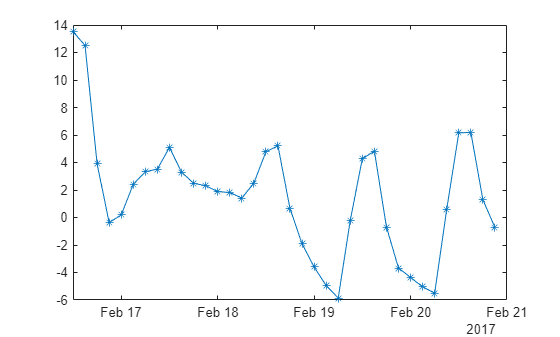

plot(time,temp,'-*')

## Retime and smooth data using Live Editor Tasks

Weather forecasts are only provided every 3 hours. We want to retime to have data interpolated every single hour.

T = timetable(time',temp','VariableNames',{'Temperature'})

T = 36×1 timetable
            Time            Temperature
    ____________________    ___________

    16-Feb-2017 12:00:00       13.52   
    16-Feb-2017 15:00:00       12.51   
    16-Feb-2017 18:00:00         3.9   
    16-Feb-2017 21:00:00       -0.37   
    17-Feb-2017 00:00:00       0.191   
    17-Feb-2017 03:00:00       2.418   
    17-Feb-2017 06:00:00       3.328   
    17-Feb-2017 09:00:00        3.52   
    17-Feb-2017 12:00:00       5.103   
    17-Feb-2017 15:00:00       3.305   
    17-Feb-2017 18:00:00       2.489   
    17-Feb-2017 21:00:00       2.309   
    18-Feb-2017 00:00:00       1.885   
    18-Feb-2017 03:00:00       1.815   
    18-Feb-2017 06:00:00</

% Retime timetable
newTimetable = retime(T,"regular","linear","TimeStep",hours(1))

newTimetable = 106×1 timetable
            Time            Temperature
    ____________________    ___________

    16-Feb-2017 12:00:00        13.52  
    16-Feb-2017 13:00:00       13.183  
    16-Feb-2017 14:00:00       12.847  
    16-Feb-2017 15:00:00        12.51  
    16-Feb-2017 16:00:00         9.64  
    16-Feb-2017 17:00:00         6.77  
    16-Feb-2017 18:00:00          3.9  
    16-Feb-2017 19:00:00       2.4767  
    16-Feb-2017 20:00:00       1.0533  
    16-Feb-2017 21:00:00        -0.37  
    16-Feb-2017 22:00:00       -0.183  
    16-Feb-2017 23:00:00        0.004  
    17-Feb-2017 00:00:00        0.191  
    17-Feb-2017 01:00:00      0.93333  
    17-Feb-201

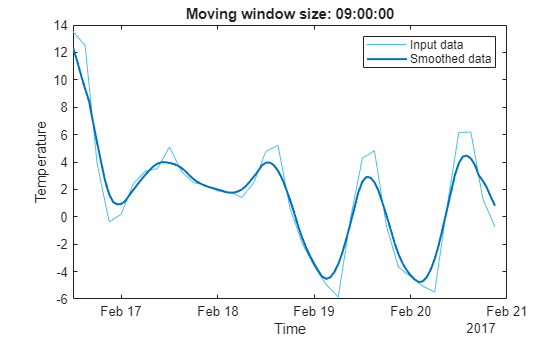

% Smooth input data
[newTable,winSize] = smoothdata(newTimetable,"movmean","SmoothingFactor",0.25);

% Display results
figure
plot(newTimetable.Time,newTimetable.Temperature,"SeriesIndex",6, ...
    "DisplayName","Input data")
hold on
plot(newTimetable.Time,newTable.Temperature,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("Temperature")
xlabel("Time")

clear winSize

## Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

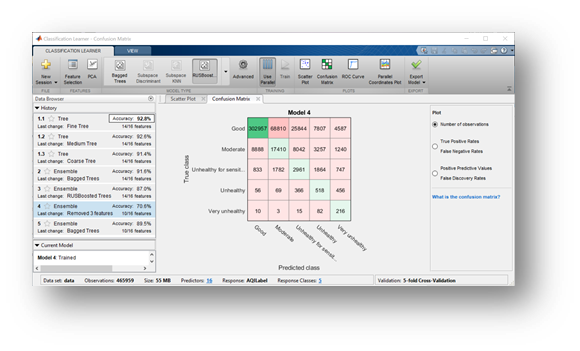

Use a function (`prepData.m`) to convert and prepare data for machine learning (create a table with the expected variable names, preprocessing steps, etc). 

currentData = prepData(weatherData)

currentData = 1×12 table
         DateLocal            city      StateName     T       P        DP      RH    WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _________    ____    ____    ______    __    _______    _______    ____    __    __

    15-May-2025 12:09:26    "London"       UK        7.17    1012    273.48    81      80         4.1      2025    5     15


Use the model to predict the air quality for the new weather data.

'*airQualModel.mat*' contains a pre-trained Bagged Classification Tree/ "Random Forest" classification network. The network was trained using a large data set stored on a local HDFS cluster (~1TB of historical weather data) and required the use of the "tall" MATLAB datatype.  The model was saved as a *.mat file for use in predicting air quality in this demonstration. 

load airQualModel model

airQual = predict(model,currentData)

airQual = categorical
     Good 


## Share prediction code

Create a function with these steps to be called in the Python environment.

edit("predictAirQual.m")

See `CallMATLABfromPython.ipynb`

## Reload Python module

Reload *weather.py *after modifications:

% clear classes
% mod = py.importlib.import_module('weather'); 
% py.importlib.reload(mod);

Read the documentation to know more:

[Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/releases/R2015b/matlab/matlab_external/call-modified-python-module.html)

**Helper Functions**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end